# Final Presentation: Use of the Kuka LBR iiwa in an Automotive Sealant Application

* Robert Garrone, Blerand Qeiriqi, Tejinder Jutla*

*    Worcester Polytechnic Institute*

## Introduction:

For the final presentation, we are asked to propose the Kuka LBR iiwa robot for use in an industry application to upper management. In the proposal, we are specifically asked to:

- Investigate the payload, precision, speed, safety, configuration

- Use all tools and items you learned in this class.

- Discuss the size and cost

- Use Robotics Toolkit, ROS, visualization, and animation effects. 

### Approach:

The approach taken is to identify a suitable use-case for our given manipulator. Our work builds upon and borrows from the previous work we have done with the Kuka LBR, with particular focus on the work undertaken to describe the manipulator's singularities and its tracjtory planning. As the Kuka LBR is a well-established industrial manipulator, there exist many applications for which the Kuka LBR would be well-suited. Given this, we researched the case studies provided by Kuka for inspiration for a task that the Kuka LBR could feasibly perform and provide value. After careful consideration, the group decided upon employing the Kuka LBR to apply sealant to an oil pan after [observing sealants being applied in production at a Ford plant in Germany](https://www.kuka.com/en-us/industries/solutions-database/2019/05/body-in-white-production-ford-lbriiwa_sys), as group members have either hobby interest in automobiles or have experience with adhesive processes. 

To demonstrate the feasibility of this process, the group researched the cost, safety considerations and feasibility of using the Kuka LBR for this purpose. We present the manipulator specifications, the cost information for deploying the manipulator for this purpose and a technical analysis of the Kuka LBR with an animation showing a possible trajectory for dispensing sealant onto the oil pan of a commerically available automobile, the 2015 Nissan Titan. 

### Problem Definition:

In modern day automobiles, many different sealants are applied to various joints. One of these is a silicone sealant on the oil pan of the car. For our project, we will be looking at the 2015 Nissan Titan which is a full-size truck equipped with a 5.6-liter V8 with a 5-speed automatic transmission and its oil pan, which has a sealant applied at the rubber gasket..

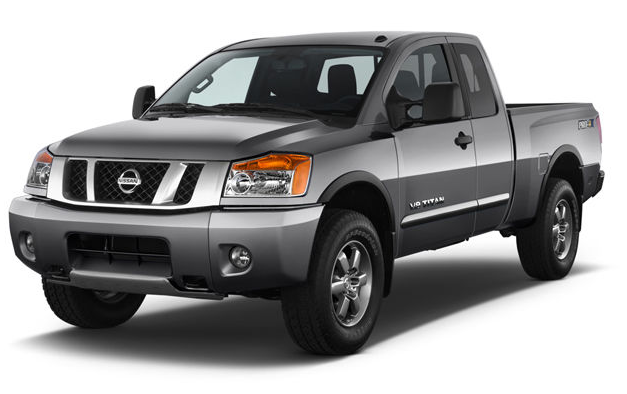

*The 2015 Nissan Titan*

In this truck, we will focus on the transmission oil pan sealing process. The process of applying a silicone adhesive ensures the transmission oil pan will now be sealed and continue to function as intended. Sometimes, however, the technician can make mistakes as the application of the silicone sealant is all manually done with the visual guide of the technician’s sight. This can lead to premature failure of the seal or even immediate failure, which will result is re-doing the job and/or spilling transmission fluid on the road which will pollute the environment and require maintanence..

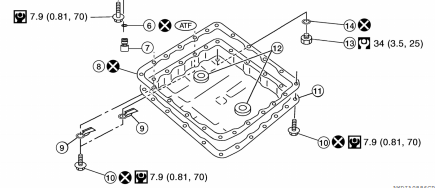

*The oil pan for a Nissan Titan (item 11) as well as its gasket (item 8) where an RTV adhesive is applied when remating the oil pan to the bottom of the engine*

Our group proposes a solution to this task. We plan on demonstrating how our KUKA LBR robotic arm can apply RTV silicon sealant to the oil pan with vast improvements in efficiency, precision and most importantly a reduction in potential human error. With this solution, the technician can work on other tasks as the KUKA LBR robot applies the sealant, making the job overall very efficient.

## Materials and Methods:

### Manipulator Background:

The KUKA LBR robot is a 7-Link Robot where all of the joints are revolute. The Kuka Robot has a weight capacity of 7 to 14kg (depending on the model) and it is meant to be used for lightweight applications. With a rating of greater than 30,000 hours of operation this robot has proven to be very reliable. In hand, with its IP54 rating, the KUKA LBR robot will be able to be used in all types of normal machine environments. With it’s embedded torque sensors in all 7 axes, the kuka robot is setting an industry standard for safe collision protection by reacting to even the slightest external forces.This eliminates the need for a safety fence and therefore also the requirement for high costs and increased complications with the robotic implementation especially when it comes to human robot interactions. With a low weight of 22 kg, the kula robot can be easily mounted in almost all situations or can be even mobile under correct safety conditions. 

The specifications of the KUKA robot are also some of the best in the industry. With a repeatability of +/- 0.1mm the KUKA robot has the capability of performing all movements to many degrees of accuracy. Also a precision of 2% torque accuracy for each of the joints the KUKA will always apply the perfect amount of torque on any object, something that is extremely necessary when dealing with components of this nature. With a capacity to reach a wide range of distances from a very compact frame the KUKA is a perfect candidate for use in very tight situations. The figure below shows the workspace of the KUKA.

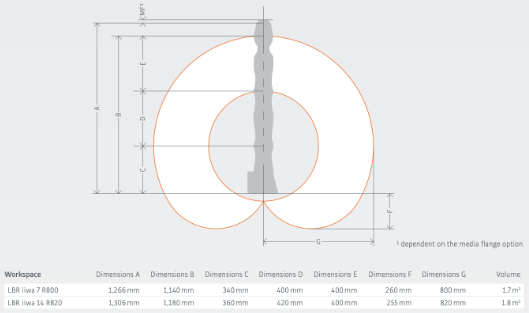

*Kuka LBR Workspace Envelope*

From the trajectory map you can see that the KUKA robot has a wide range of positions it can reach. The table below shows the torques and the maximum velocities for each of the joints

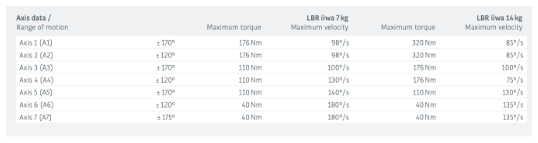

*Kuka LBR maximuum speeds and torques for each joint*

The joints offer a great deal of flexibility in terms of range of motion, velocity and torque. This allows the KUKA to be very well placed in terms of being able to meet almost all situations.

The KUKA robot has a price tag of around $200,000 however, with that price tag comes a robotic system which can meet a range of different situations repeatedly and accurately. This robot will be very well inclined to complete very low-weight tasks and creating better solutions for any operation that the KUKA robot can meet the requirements. 

### Singularity Theory and Consderations:

The two major types of singularites are arm singularities and wrist singularities. Wrist singularities occur when any 2 revolute joint axes are collinear with one another. In this configuration, equal and opposite rotation about the axes results in no net motion of the end-effector. This is the only singularity of the spherical wrist,and is unavoidable without imposing mechanical limits on the wrist design to restrict its motion in such a way that $z_3 \;\textrm{and}\;z_5$ are prevented from lining up. 

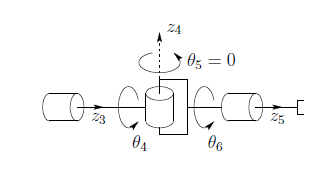

Arm singularies are entirely described by the determinant of $J_{11}$ and occur for 2 different conditions. One such configuration is where an arm is fully extended and is at maximum reach or is fully retracted. The other configuration is where the rotation axis of the base frame is aligned with the wrist center or end effector of a manipulator. The singular configurations for an articulated manipulator arm for this are shown to illustrate. 

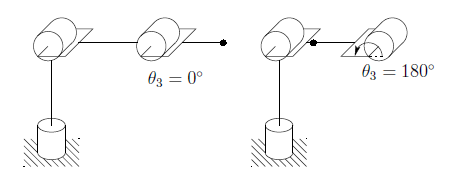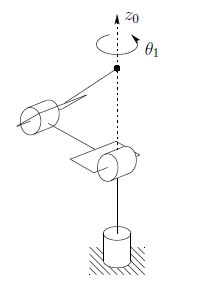

On the second case more specifically, it is precisely when $a_2 c_2 =-a_3 c_{23}$. For simplicity, if $a_2 =a_3$ then the singularity occurs when $c_2 =-c_{23}$, implying that the sum of $\theta_2 +\theta_3$ is exactly eqal and opposite in sign from $\theta_2$. In this configuration, any rotation by $\theta_1$ yields no change in end effector position. 

The Kuka LBR iiwa has four *kinematic* singularities as described in its programming reference and are shown below:

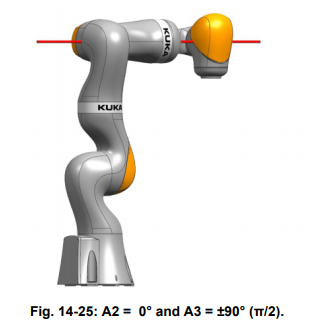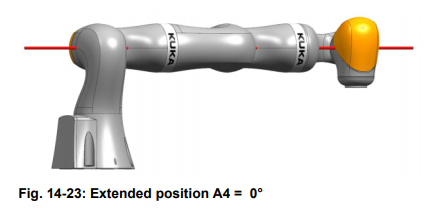

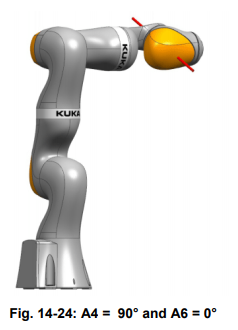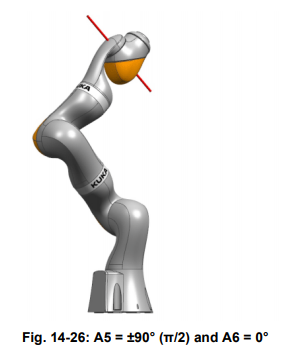

Additionally, Kuka describes the following *system dependent *(i.e. wrist singularities and shoulder singularities) where either the wrist is aligned with the joint axis of link 1 or the wrist $\theta_6 =0$, aligning joints 5 and 7:

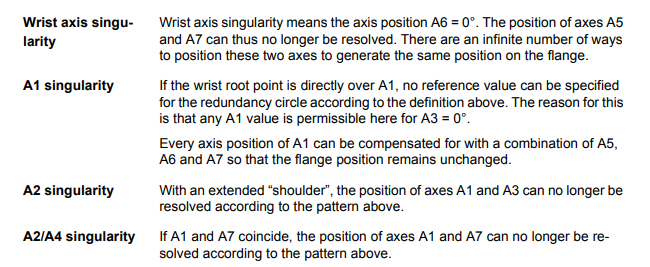

### Trajectory Planning Theory and Considerations:

The Joint Space is the set of all the joint angles that ultimately define the end-effector position and orientation.  In order to get the Joint Space trajectory for the Kuka robot, first identify the start and end points of the end effector, use inverse kinematics to calculate the individual joint angle positions for the start and end points of the end effector and then create waypoints in between the start and end joint angle positons for each individual joint. Since our robot is a 7-Link RRRRRRR Robot, the joint space is

 $q=\left\lbrace \theta_1 ,\theta_2 ,\theta_3 ,\theta_4 ,\theta_5 ,\theta_6 ,\theta_7 \right\rbrace$.

The Task Space is the space in which the robot end-effector can be specified. In other words, it is the set of all possible end-effector poses.For the Kuka LBR, the end effector can be described by maximally 6 attributes, 3 for position and 3 for orientation:


$$\chi_E ~\left(x,y,z,\psi ,\theta ,\phi \right)$$


Which are coordinates x, y and z, and angular orientation variables *yaw, pitch* and *roll *respectively.

From this we can say that because the Kuka LBR has a $\textrm{DOF}\ge 6$ that task space $T\subset \textrm{SE}\left(3\right)$.

In order to get the Task Space trajectory for the Kuka robot, first identify the start and end points of the end effector, and then create waypoints in between the start and end end-effector positons. The task space trajectory is created by solving for the inverse kinematics for each of these end-effector waypoints.

The task-space approach has the advantage of greater end-effector "precision" and predictablity in that the trajectory is a straight line from the start to end position. However, the disadvantage to this approach is the computational intensity needed to employ this method (i.e. the need to solve the inverse kinematics problem for each end effector waypoint). Conversely, the joint-space approach is a computationally simpler method in that the inverse kinematics problem only has to be solved for the start and end positions but has the disadvantage of producing a trajectory that is less direct (i.e. a curved line).

Given our problem statement, it is advantageous to use the *task-space approach* as it is necessary for the Kuka LBR to execute a trajectory on a series of precise straight paths as opposed to the curved path that the joint-space approach would produce.

## Results

### Manipulator DH Table Defintion:

Faria et al. Gives a convenient DH convention diagram of the Kuka LBR robot. It is reproduced below with each link length clearly indicated.

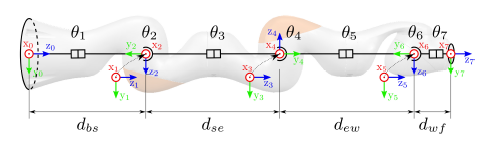

A DH table is also provided by Faria et al. for the Kuka LBR and is reproduced below:

 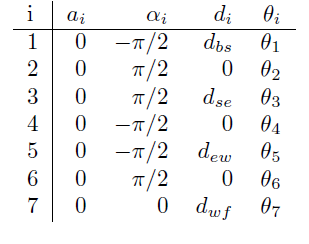

We now can realize this DH table in MATLAB: 

%from Faria et al.

syms 'a%d' 'alpha%d' 'theta%d' [1 7]
syms 'd_bs' 'd_se' 'd_ew' 'd_wf'

%Create DH Table
dh_table = [
    0 -pi/2 d_bs theta1;
    0  pi/2 0    theta2;
    0  pi/2 d_se theta3;
    0 -pi/2 0    theta4;
    0 -pi/2 d_ew theta5;
    0  pi/2 0    theta6;
    0  0    d_wf theta7;]

$$dh\_table = \left(\begin{array}{cccc} 0 & -\frac{\pi }{2} & d_{\mathrm{bs}} & \theta_{1}\\ 0 & \frac{\pi }{2} & 0 & \theta_{2}\\ 0 & \frac{\pi }{2} & d_{\mathrm{se}} & \theta_{3}\\ 0 & -\frac{\pi }{2} & 0 & \theta_{4}\\ 0 & -\frac{\pi }{2} & d_{\mathrm{ew}} & \theta_{5}\\ 0 & \frac{\pi }{2} & 0 & \theta_{6}\\ 0 & 0 & d_{\mathrm{wf}} & \theta_{7} \end{array}\right)$$


%dims in meters from
%Kuka LBR iiwa7 R800 brochure
d_bs= 0.340 %base to shoulder

d_bs = 0.3400

d_se= 0.400 %shouled to elbow 

d_se = 0.4000

d_ew= 0.400 %elbow to wrist

d_ew = 0.4000

d_wf= 0.126 %wrist to to end effector

d_wf = 0.1260


%dh table w/ link lengths added.
dh_table = subs(dh_table)

$$dh\_table = \left(\begin{array}{cccc} 0 & -\frac{\pi }{2} & \frac{17}{50} & \theta_{1}\\ 0 & \frac{\pi }{2} & 0 & \theta_{2}\\ 0 & \frac{\pi }{2} & \frac{2}{5} & \theta_{3}\\ 0 & -\frac{\pi }{2} & 0 & \theta_{4}\\ 0 & -\frac{\pi }{2} & \frac{2}{5} & \theta_{5}\\ 0 & \frac{\pi }{2} & 0 & \theta_{6}\\ 0 & 0 & \frac{63}{500} & \theta_{7} \end{array}\right)$$

### Defining the Manipulator from a URDF File:

We start by defining the Kuka robot. Here we can import the Kuka LBR iiwa URDF (Unified Robotic Description Format) file to define the robot as it provides a better visual representation than a DH table derived model would provide. MATLAB has a built-in URDF file for this particular manipulator, which we will use. We set and view its home configuration to confirm that it meets our expectations. 

clear all
clf
%%% Define robot %%%
robot = importrobot('iiwa7.urdf')

robot =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'iiwa_link_0'  'iiwa_link_1'  'iiwa_link_2'  'iiwa_link_3'  'iiwa_link_4'  'iiwa_link_5'  'iiwa_link_6'  'iiwa_link_7'  'iiwa_link_ee'  'iiwa_link_ee_kuka'}
      BaseName: 'world'
       Gravity: [0 0 0]
    DataFormat: 'struct'


initConfig = robot.homeConfiguration()

initConfig = 1×7 struct array with fields:
    JointName
    JointPosition


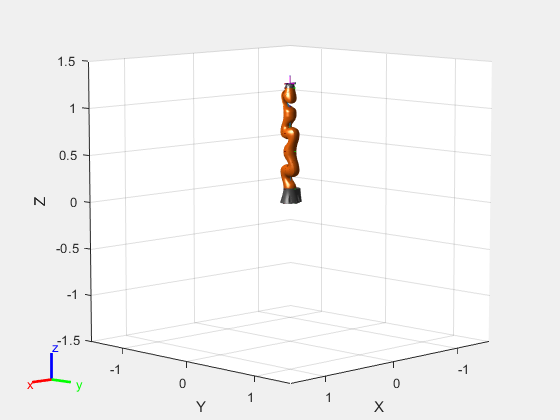

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(robot,initConfig)

### Defining Major Trajectory Points for the Sealant Application Path:

To begin, we define four homogeneous transforms that specify our desired rectangular path. In lieu of formal dimensions for the oil pan, we make the reasoned assumption that the rectangular oil pan is roughly 200mm x 300mm. We assume the workpiece to be positioned on a flat surface arbitrarily 0.5m high.

It is possible to create a 200mm x 300mm rectangular trajectory from 4 consecutive paths. We begin by defining the starting and ending homogeneous transforms or starting and ending coordinate frames for each path. The general trajectory path is:

- H1 -> H2

- H2 -> H3

- H3 -> H4

- H4 -> H1

The H1-H4 frames are realizable in code as shown below.

%%% Define ConfigH1-H4 %%%

%End effector positioning and oriented so that it is pointed directly down
%to interface w/ the workpiece
ConfigH1 = trvec2tform([.5, .5, .5])*axang2tform([1,0,0,pi])

ConfigH1 =     1.0000         0         0    0.5000
         0   -1.0000   -0.0000    0.5000
         0    0.0000   -1.0000    0.5000
         0         0         0    1.0000


ConfigH2 = trvec2tform([.3, .5, .5])*axang2tform([1,0,0,pi])

ConfigH2 =     1.0000         0         0    0.3000
         0   -1.0000   -0.0000    0.5000
         0    0.0000   -1.0000    0.5000
         0         0         0    1.0000


ConfigH3 = trvec2tform([.3, .2, .5])*axang2tform([1,0,0,pi])

ConfigH3 =     1.0000         0         0    0.3000
         0   -1.0000   -0.0000    0.2000
         0    0.0000   -1.0000    0.5000
         0         0         0    1.0000


ConfigH4 = trvec2tform([.5, .2, .5])*axang2tform([1,0,0,pi])

ConfigH4 =     1.0000         0         0    0.5000
         0   -1.0000   -0.0000    0.2000
         0    0.0000   -1.0000    0.5000
         0         0         0    1.0000


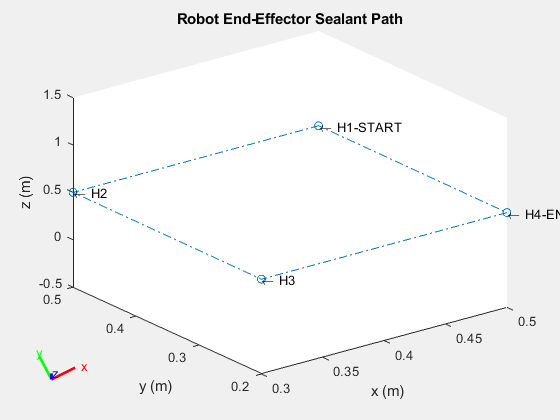


%get the 4th column to show translation from frame to frame
ConfigH1pt = ConfigH1(:,4);
ConfigH2pt = ConfigH2(:,4);
ConfigH3pt = ConfigH3(:,4);
ConfigH4pt = ConfigH4(:,4);

%Plot the H's as points in space
plot3([ConfigH1pt(1,1), ConfigH2pt(1,1), ConfigH3pt(1,1),ConfigH4pt(1,1),ConfigH1pt(1,1)], ...
    [ConfigH1pt(2,1), ConfigH2pt(2,1),ConfigH3pt(2,1),ConfigH4pt(2,1),ConfigH1pt(2,1)], ...
    [ConfigH1pt(3,1), ConfigH2pt(3,1),ConfigH3pt(3,1),ConfigH4pt(3,1),ConfigH1pt(3,1)],'-.o')
%labels and titles
title('Robot End-Effector Sealant Path')
xlabel('x (m)')
ylabel('y (m)')
zlabel('z (m)')
text(ConfigH1pt(1,1),ConfigH1pt(2,1),ConfigH1pt(3,1),"\leftarrow H1-START");
text(ConfigH2pt(1,1),ConfigH2pt(2,1),ConfigH2pt(3,1),"\leftarrow H2");
text(ConfigH3pt(1,1),ConfigH3pt(2,1),ConfigH3pt(3,1),"\leftarrow H3");
text(ConfigH4pt(1,1),ConfigH4pt(2,1),ConfigH4pt(3,1),"\leftarrow H4-END");

With the start and end frames defined for each linear trajectory, we may initialize the `inverseKinematics()` solver and visualize the manipulator's pose at each of the 4 defined frames by solving for the individual joint positions. 

clf
%Set up ik solver object
ik = inverseKinematics('RigidBodyTree',robot);
weights= [1 1 1 1 1 1];
endEffector = 'iiwa_link_ee_kuka'

endEffector = 'iiwa_link_ee_kuka'

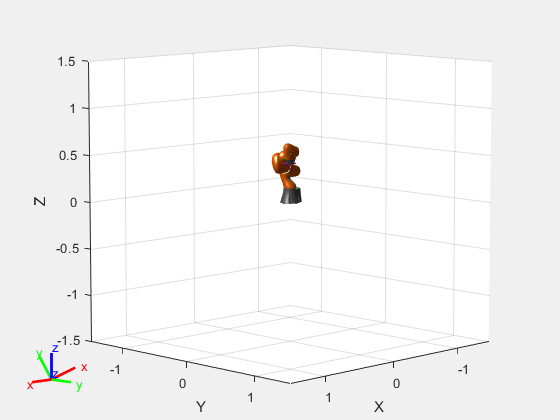

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


guess = robot.homeConfiguration();

%solve and show for config 1
[Config1Sol,solInfo] = ik(endEffector,ConfigH1,weights,guess);
show(robot,Config1Sol)


% hold on %uncomment for single layered figure of manipulator. Kinda cool.

%Check that ConfigSol yields what we expect
Config1H_ik = getTransform(robot,Config1Sol,['iiwa_link_ee_kuka'])

Config1H_ik =     1.0000    0.0000   -0.0000    0.5000
    0.0000   -1.0000   -0.0000    0.5000
   -0.0000    0.0000   -1.0000    0.5000
         0         0         0    1.0000


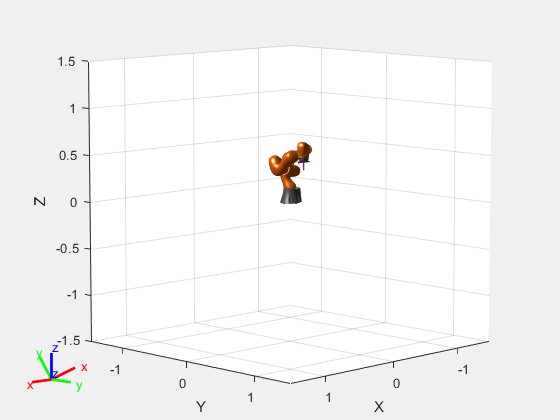

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


%update guess
guess = Config1Sol;

%solve and show for config 2
[Config2Sol, solInfo] = ik(endEffector,ConfigH2,weights,guess);
show(robot,Config2Sol)


%Check that ConfigSol yields what we expect
Config2H_ik = getTransform(robot,Config2Sol,['iiwa_link_ee_kuka'])

Config2H_ik =     1.0000    0.0000    0.0000    0.3000
    0.0000   -1.0000   -0.0000    0.5000
    0.0000    0.0000   -1.0000    0.5000
         0         0         0    1.0000


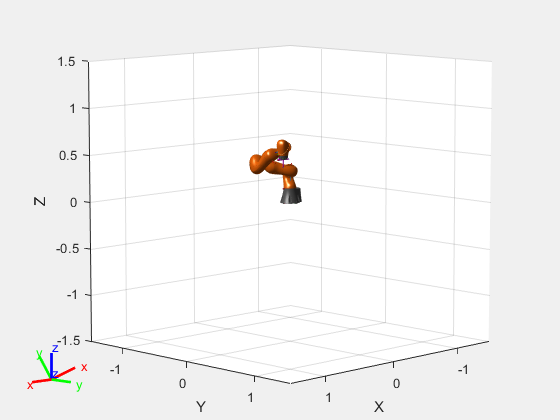

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


%update guess
guess = Config2Sol;

%solve and show for config 3
[Config3Sol,solInfo] = ik(endEffector,ConfigH3,weights,guess);
show(robot,Config3Sol)


%Check that ConfigSol yields what we expect
Config3H_ik = getTransform(robot,Config3Sol,['iiwa_link_ee_kuka'])

Config3H_ik =     1.0000    0.0000    0.0000    0.3000
    0.0000   -1.0000   -0.0000    0.2000
    0.0000    0.0000   -1.0000    0.5000
         0         0         0    1.0000


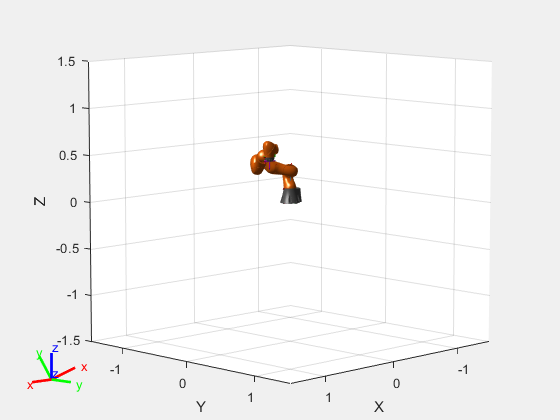

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


%update guess
guess = Config3Sol;

%solve and show for config 4
[Config4Sol,solInfo] = ik(endEffector,ConfigH4,weights,guess);
show(robot,Config4Sol)


%Check that ConfigSol yields what we expect
Config4H_ik = getTransform(robot,Config4Sol,['iiwa_link_ee_kuka'])

Config4H_ik =     1.0000    0.0000    0.0000    0.5000
    0.0000   -1.0000    0.0000    0.2000
    0.0000   -0.0000   -1.0000    0.5000
         0         0         0    1.0000


%update guess
%guess = Config4Sol;

%Debug - again make sure we don't land ON a singularity
%replace endConfigSol w/ any of the 4 solutions above.
%finishJ = geometricJacobian(robot,endConfigSol,'iiwa_link_ee_kuka')
%rank(finishJ) %6 is max and what ought to show up.


With `getTransform,` we see that the inverse kinematics solver has produced the same 4x4 homogeneous matrices as we initially defined for all 4 major configurations, which verifies that the joint angles calculated for each pose are correct. 

### Task-Space Trajectory Planning Setup:

The method used to define the sealant path is the task space method. We realize the task space approach by defining waypoints for the end effector that are interpolated in between the start and end points of a given trajectory path. In our case, we have 4 points that we must define waypoints between. 

To create the waypoints, we define a timestep and a constant tool speed. Based on MATLAB tutorials for trajectory planning, we use 0.1 seconds as the timestep and 0.1 m/s as the tool speed. 

We may calculate the Euclidian distance between the start and end points of the trajectory and calculate the trajectory time by dividing this distance by the tool speed specified. From this calculation, we may further define a linear space of times (`trajTimes`). 

%%% Task Space traj planning %%%
%waypoints from startconfig to endconfig

%Define timestep and toolSpeeed - assumes constant speed.
timestep = 0.25 %seconds

timestep = 0.2500

toolSpeed = 0.1 %m/s

toolSpeed = 0.1000


%Calc Euclidian distances between H's
distance12 = norm(tform2trvec(ConfigH1)-tform2trvec(ConfigH2))

distance12 = 0.2000

distance23 = norm(tform2trvec(ConfigH2)-tform2trvec(ConfigH3))

distance23 = 0.3000

distance34 = norm(tform2trvec(ConfigH3)-tform2trvec(ConfigH4))

distance34 = 0.2000

distance41 = norm(tform2trvec(ConfigH4)-tform2trvec(ConfigH1))

distance41 = 0.3000


%Calc and define time interval from 1 to 2
initTime12 = 0; %begin at t=0
finalTime12 = (distance12/toolSpeed) + initTime12; %d/v = t
trajTimes12 = initTime12:timestep:finalTime12;
timeInterval12 = [trajTimes12(1); trajTimes12(end)]

timeInterval12 =      0
     2



%Calc and define time interval from 2 to 3
initTime23 = finalTime12; %begin at last interval's final time
finalTime23 = (distance23/toolSpeed) + initTime23; %d/v = t
trajTimes23 = initTime23:timestep:finalTime23;
timeInterval23 = [trajTimes23(1); trajTimes23(end)]

timeInterval23 =      2
     5



%Calc and define time interval from 3 to 4
initTime34 = finalTime23; %begin at last interval's final time
finalTime34 = (distance34/toolSpeed) + initTime34; %d/v = t
trajTimes34 = initTime34:timestep:finalTime34;
timeInterval34 = [trajTimes34(1); trajTimes34(end)]

timeInterval34 =      5
     7



%Calc and define time interval from 1 to 2
initTime41 = finalTime34; %begin at last interval's final time
finalTime41 = (distance41/toolSpeed) + initTime41; %d/v = t
trajTimes41 = initTime41:timestep:finalTime41;
timeInterval41 = [trajTimes41(1); trajTimes41(end)]

timeInterval41 =      7
    10



disp("The total rectangular trajectory time is " + (trajTimes41(end)-trajTimes12(1)) + " seconds.")

The total rectangular trajectory time is 10 seconds.


The total time for the Kuka LBR to execute the trajectory is displayed above. 

Given all of these defined variables, we can obtain a series of "frame" waypoints (i.e. homogeneous 4x4 matricies that define the position and orientaiton of the end effector at different points in the trajectory) by using the function `transformtraj 4 times`, and passing it the start and end frames `ConfigH1` through `ConfigH4` for each linear trajectory that defines the ultimate rectangular path`. `

%get end effector waypoints
taskWaypoints12 = transformtraj(ConfigH1,ConfigH2,timeInterval12,trajTimes12); 
taskWaypoints23 = transformtraj(ConfigH2,ConfigH3,timeInterval23,trajTimes23); 
taskWaypoints34 = transformtraj(ConfigH3,ConfigH4,timeInterval34,trajTimes34); 
taskWaypoints41 = transformtraj(ConfigH4,ConfigH1,timeInterval41,trajTimes41); 

%debug - plot the waypoints 
% array_point_x = zeros(size(taskWaypoints,3),1);
% array_point_y = zeros(size(taskWaypoints,3),1);
% array_point_z = zeros(size(taskWaypoints,3),1);
% 
% for i = 1:size(taskWaypoints,3)
%     point = taskWaypoints(1:3,4,i);
%     array_point_x(i) = point(1,1);
%     array_point_y(i) = point(2,1); 
%     array_point_z(i) = point(3,1);
% end

%plot end effector waypoints
% plot3(array_point_x,array_point_y,array_point_z, '-.o');

### Task Space Waypoint Generation:

To actually calculate the trajectory via a task-space approach, we pass the task space waypoints, `taskWaypoints`, calculated above to the `inverseKinematics() `solver in a for loop, have the solver solve the individual joint positions for each pose defined by the 4x4 homogeneous matrix "waypoints", and collect those waypoint-by-waypoint solutions in a positions solutions matrix, `qs`. We do this for each of the 4 defined linear paths.

ik = inverseKinematics('RigidBodyTree',robot);
count12  = length(trajTimes12);
count23  = length(trajTimes23);
count34  = length(trajTimes34);
count41  = length(trajTimes41);

weights= [1 1 1 1 1 1];
guess = Config1Sol;
ndof = length(guess);
qs12 = zeros(count12,ndof);
qs23 = zeros(count23,ndof);
qs34 = zeros(count34,ndof);
qs41 = zeros(count41,ndof);

%1 to 2
for i = 1:size(taskWaypoints12,3)
    pose = taskWaypoints12(:,:,i);
    q_Sol = ik(endEffector,pose,weights,guess);
    qs12(i,:)=[q_Sol(1).JointPosition q_Sol(2).JointPosition q_Sol(3).JointPosition q_Sol(4).JointPosition...
        q_Sol(5).JointPosition,q_Sol(6).JointPosition,q_Sol(7).JointPosition];
    guess = q_Sol;
end

%2 to 3
guess=Config2Sol;
for i = 1:size(taskWaypoints23,3)
    pose = taskWaypoints23(:,:,i);
    q_Sol = ik(endEffector,pose,weights,guess);
    qs23(i,:)=[q_Sol(1).JointPosition q_Sol(2).JointPosition q_Sol(3).JointPosition q_Sol(4).JointPosition...
        q_Sol(5).JointPosition,q_Sol(6).JointPosition,q_Sol(7).JointPosition];
    guess = q_Sol;
end

%3 to 4
guess=Config3Sol;
for i = 1:size(taskWaypoints34,3)
    pose = taskWaypoints34(:,:,i);
    q_Sol = ik(endEffector,pose,weights,guess);
    qs34(i,:)=[q_Sol(1).JointPosition q_Sol(2).JointPosition q_Sol(3).JointPosition q_Sol(4).JointPosition...
        q_Sol(5).JointPosition,q_Sol(6).JointPosition,q_Sol(7).JointPosition];
    guess = q_Sol;
end

%4 to 1
guess=Config4Sol;
for i = 1:size(taskWaypoints41,3)
    pose = taskWaypoints41(:,:,i);
    q_Sol = ik(endEffector,pose,weights,guess);
    qs41(i,:)=[q_Sol(1).JointPosition q_Sol(2).JointPosition q_Sol(3).JointPosition q_Sol(4).JointPosition...
        q_Sol(5).JointPosition,q_Sol(6).JointPosition,q_Sol(7).JointPosition];
    guess = q_Sol;
end

### Checking for Singularities in the Trajectory Path:

Before we plot the trajectory, each linear trajectory component of the rectangular path can be checked to ensure that no singularities are present in each of the 4 linear trajectories that define the rectangular routine. 

To do this, we make use of a custom function `check_Kuka_LBR_traj_singularities` that checks each row of the `qs` matricies for singular conditions and returns a count of singular conditions identified. 

%note: Limitations of this function are understood and documented in the function
%definition.

%Visually, nothing in our trajectory suggests a singular
%condition- no right angles between links and mid-wrist joint is not 0deg.

qs12_singularity_count=check_Kuka_LBR_traj_singularities(qs12)

qs12_singularity_count = 0


qs23_singularity_count=check_Kuka_LBR_traj_singularities(qs23)

qs23_singularity_count = 0


qs34_singularity_count=check_Kuka_LBR_traj_singularities(qs34)

qs34_singularity_count = 0


qs41_singularity_count=check_Kuka_LBR_traj_singularities(qs41)

qs41_singularity_count = 0

As all 4 trajectories have 0 reported singularities in them, we have confidence that the path is realizable and can proceed to assigning the trajectory to the Kuka LBR for realization.

### Plotting the Rectangular Trajectory:

Next, we can use the solutions matricies `qs12` through `qs41` to plot the task space trajectory of the end effector 

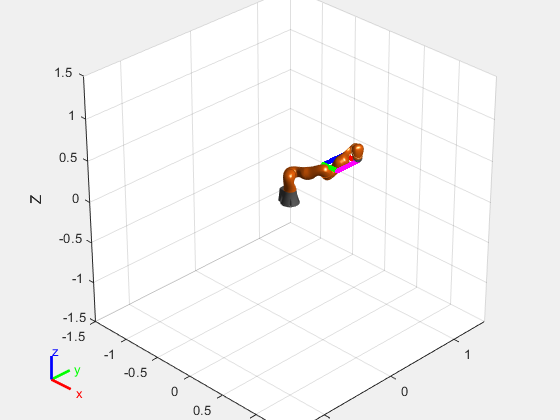

%to be safe, clear figure.
clf

%take transposes to get each row as joint position
qs12_transpose = qs12';
qs23_transpose = qs23';
qs34_transpose = qs34';
qs41_transpose = qs41';

%need a starting pose
plotTaskSpaceConfig = Config1Sol;

%show initial pose of robot and hold on for animation
show(robot,Config1Sol,'PreservePlot',false,'Frames','off');
view([45,30])
hold on

%loop to assign robot to poses in 1 to 2, 
%draw animation of robot moving through trajectory. 
for i = 1:size(qs12_transpose,2)
    %assign joint positions
    for j = 1:7
        plotTaskSpaceConfig(j).JointPosition = qs12_transpose(j,i);
    end
    show(robot,plotTaskSpaceConfig);
    poseNow = getTransform(robot,plotTaskSpaceConfig,endEffector);
    %show robot in config specified in each iteration of outer loop
    show(robot,plotTaskSpaceConfig,'PreservePlot',false,'Frames','off');
    %superimpose plot of end effector on robot animation.
    plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'r.','MarkerSize',10);
    drawnow;
end

%loop to assign robot to poses in 2 to 3, 
%draw animation of robot moving through trajectory. 
for i = 1:size(qs23_transpose,2)
    %assign joint positions
    for j = 1:7
        plotTaskSpaceConfig(j).JointPosition = qs23_transpose(j,i);
    end
    show(robot,plotTaskSpaceConfig);
    poseNow = getTransform(robot,plotTaskSpaceConfig,endEffector);
    %show robot in config specified in each iteration of outer loop
    show(robot,plotTaskSpaceConfig,'PreservePlot',false,'Frames','off');
    %superimpose plot of end effector on robot animation.
    plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'b.','MarkerSize',10);
    drawnow;
end

%loop to assign robot to poses in 3 to 4, 
%draw animation of robot moving through trajectory. 
for i = 1:size(qs34_transpose,2)
    %assign joint positions
    for j = 1:7
        plotTaskSpaceConfig(j).JointPosition = qs34_transpose(j,i);
    end
    show(robot,plotTaskSpaceConfig);
    poseNow = getTransform(robot,plotTaskSpaceConfig,endEffector);
    %show robot in config specified in each iteration of outer loop
    show(robot,plotTaskSpaceConfig,'PreservePlot',false,'Frames','off');
    %superimpose plot of end effector on robot animation.
    plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'g.','MarkerSize',10);
    drawnow;
end

%loop to assign robot to poses in 4 to 1, 
%draw animation of robot moving through trajectory. 
for i = 1:size(qs41_transpose,2)
    %assign joint positions
    for j = 1:7
        plotTaskSpaceConfig(j).JointPosition = qs41_transpose(j,i);
    end
    show(robot,plotTaskSpaceConfig);
    poseNow = getTransform(robot,plotTaskSpaceConfig,endEffector);
    %show robot in config specified in each iteration of outer loop
    show(robot,plotTaskSpaceConfig,'PreservePlot',false,'Frames','off');
    %superimpose plot of end effector on robot animation.
    plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'m.','MarkerSize',10);
    drawnow;
end

The results of the task space trajectory simulation are shown with the trajectory in red, blue green and magenta for trajectories 1 to 2, 2 to 3, 3 to 4 and 4 to 1 respectively. Below is a detailed view of the realized rectangular trajectory.

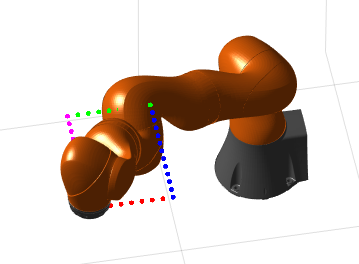

*The Kuka LBR executing the rectangular trajectory described. *

##  Discussion:

### Technical Considerations:

This group has demonstrated that the Kuka LBR can sucessfully execute a rectangular path in a highly reliable and repeatable pattern. The accuracy of $\pm$0.1mm of the manipulator ensures that the silicone adhesive will be applied in a consistent and repeatable manner with minimal variation from component to component. The path demonstrated has been proven to contain no singularities and is readily executable.

Further investigation is needed into the dispensing method employed in conjunction with the Kuka LBR. Variables such as rate of flow, valve aperature size and environmental conditions must also be considered. Considerations for an adheaive process must include cure time for the sealant and how to deal with curing during process idle time. One solution may be a programmable "purge" function that discharges adhesive from the nozzle into a recepatacle periodically to prevent the adhesive from curing prior to application. 

Ultimately, the Kuka LBR's applicability to the manufacturing process is eminently scalable - a single manipulator can be made to execute several different sealant application operations for several different automobile models or locations within a single automobile, ensuring that the manipulator remain useful as the manufacturing process changes or evolves. 

### Cost Savings:

While the robot requires a one-time capital expense of $200k, the robot saves the company the cost of human labor to perform the same task and decreases the risk of human error in applying the sealant to the oil pan and gasket. 

In our simulation, at a conservative tool speed of 0.1 m/s, the manipulator would perform the sealant application operation in 10 seconds, which is just as fast or even faster than an operator. This will allow the manipulator to accomplish the task of applying the sealant with greater efficiency and result in greater manfufacturing throughput, saving both time and money. 

The reduction of error in sealant application will reduce the number of potential RMAs in the assembly process, improving process yield. Additionally, the use of the Kuka LBR for this process may also reduce the number of defects in the field and reduce the risk of recall and remediation for the lifetime of the Nissan Titan.

Furthermore, the fact that the Kuka LBR could potentially run constantly on an assembly line 24/7 further supports its use in the mass production on the Nissan Titan as well as on other potential automobiles. As the Kuka LBR is a general-purpose manipulator, the same unit may be used for other applications such as the application of other sealants, inspection of finished goods, and delicate operations, which further support its use in the manufacturing process. 

### Saftey Features:

The KUKA LBR robot has state of the art Torque Sensors on all 7 of its axes. This will allow even the slightest external forces to stop the Manipulator from continuing its motion. This system allows the KUKA LBR robot to be very safe for use in areas where there are not only expensive materials at use but also when there are humans in the vicinity. Normal manipulators have safety fences which can cost thousands of dollars and also reduce the capability of using robots at the same time as humans are performing tasks which reduce productivity. 

The Kuka LBR robot is also made of 100% aluminum without any sharp edges which prevents crushing or shearing hazards. Which will reduce the risk of injury to humans. This increase in safety is invaluable as it will allow humans and the manipulator to work in tandem and this will reduce costs.

### Closing Remarks:

The Kuka LBR iiwa is an apt choice for an automated sealant application in an automotive manufacturing environment. As a general-purpose lightweight robot, its duties are extendable to many more applications including quality inspection and assembly tasks. The Kuka LBR iiwa is a scalable solution for manufacturing that can easily evolve in task scope as the manufacturing process for the Nissan Titan further improves.   

## References:

-  Spong, M. W. (2006). *Robot Modelling and Control Mark W. Spong* (926186803 726311037 M. W. Spong, Author). Hoboken, NJ: Wiley.

- Faria, Carlos & Ferreira, Flora & Erlhagen, Wolfram & Monteiro, Sérgio & Bicho, Estela. (2018). Position-based kinematics for 7-DoF serial manipulators with global configuration control, joint limit and singularity avoidance. Mechanism and Machine Theory. 121. 317-334. 10.1016/j.mechmachtheory.2017.10.025. 

- [Kuka LBR Data Sheet](https://www.kuka.com/-/media/kuka-downloads/imported/6b77eecacfe542d3b736af377562ecaa/db_lbr_iiwa_en.pdf?rev=345eae49080e42f8a6db71560389e512&hash=7D620372E19F752E930B459EF31641F4)

- [Kuka Brochure](https://www.kuka.com/-/media/kuka-downloads/imported/9cb8e311bfd744b4b0eab25ca883f6d3/kuka_lbr_iiwa_brochure_en.pdf?rev=5a25f7eac825492e92af6343dbf5bc6b&hash=43592AD8D79B2D3AD91B3129988A8B8C)

- [Kuka LBR Ford Case Study](https://www.kuka.com/en-us/industries/solutions-database/2019/05/body-in-white-production-ford-lbriiwa_sys)

- [Nissan Titan Maintenance Manual](https://www.nicoclub.com/service-manual?fsm=Titan%2F2015%2Ftm.pdf)

## Defined Functions

function singularity_count = check_Kuka_LBR_traj_singularities(qsmatrix)

%%%Checks waypoints for the Kuka LBR to ensure we don't land on singularities

%%% INPUT: a matrix defining a series of individual joint angles for the
%%% Kuka LBR Manipulator

%%% OUTPUT: A count of the singularities encountered. Function will display
%%% an error indicating the nature of the singularity.

%CAVEAT EMPTOR: this only ensures that the discrete waypoints aren't landing on singular conditions
%The CONTINUOUS path may still contain singularities. 


    %Start singularity counter
    singularity_count = 0;
    
    %loop over the rows of qsmatrix
    for i=1:size(qsmatrix,1)
    %each row of qsmatrix represents individual joint positions.
    %each column is an individual joint (joints 1 through 7)
    
    %specify ith row to check for singularities
    row_to_check=qsmatrix(i,:);
    
    %Each of the 4 kinematic singularities is checked below:
    
    %CASE A4 = 0
    if row_to_check(1,4) == 0
       singularity_count = singularity_count +1;
       disp("A4 = 0deg singularity detected!")
    end
    
    %CASE A4 = pi/2, A6 = 0
    if (row_to_check(1,4) == pi/2) & (row_to_check(1,6)==0) 
        singularity_count = singularity_count +1;
        disp("A4 = 90deg and A6= 0deg singularity detected!")
    end
    
    %CASE A2 = 0, A3 = +/-90
    if ((row_to_check(1,3) == pi/2) |(row_to_check(1,3)==-pi/2)) & (row_to_check(1,2)==0) 
        singularity_count = singularity_count +1;
        disp("A3 = +/-90deg and A2= 0deg singularity detected!")
    end
    
    %CASE A6 = 0, A5= +/-90
    if ((row_to_check(1,5) == pi/2) |(row_to_check(1,5)==-pi/2)) & (row_to_check(1,6)==0) 
        singularity_count = singularity_count +1;
        disp("A5 = +/-90deg and A6= 0deg singularity detected!")
    end
    
    %DEBUG - print singularites detected by row
    %disp(singularity_count + " singularities detected.")
    end
end

function r_matrix = create_rotation_matrix(x, y, z)
    % This function creates a rotation matrix using roll (z), pitch (y),
    % and yaw (x) angles
    r_x_matrix = [1 0 0 ; 0 cos(x) -sin(x) ; 0 sin(x) cos(x)];
    r_y_matrix = [cos(y) 0 sin(y); 0 1 0; -sin(y) 0 cos(y)];
    r_z_matrix = [cos(z) -sin(z) 0; sin(z) cos(z) 0; 0 0 1];
    r_matrix = r_z_matrix * r_y_matrix * r_x_matrix;
end

function h_matrix = create_homogenous_matrix(x,y,z,dx,dy,dz)
    r_matrix = create_rotation_matrix(x,y,z);
    d_vector = [dx; dy; dz];
    h_matrix = [r_matrix d_vector; 0 0 0 1];
end

function dh_matrix = create_dh_matrix(a, alpha, d, theta)
    dh_matrix = [
      cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta);
      sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
      0,          sin(alpha),           cos(alpha),             d;
      0,            0,                  0,                      1];
end

function [A_0_n, A_i_array, A_0_i_array] = create_A_0_n_matrix(a, alpha, d, theta)
    % This function creates several dh transformation matrices and
    % multiplies them together to give one final transformation matrix
    % Inputs are 1xn matrices representing the dh params for each link
    % Output is a 4x4 dh matrix representing the ovrall transform for all
    % given links
    
    % Find the umber of links by finding the length of the array theta
    number_of_links = size(theta,2);
    % Ensure that the arrays for alpha, a, and d are the same size as theta
    if (size(alpha,2)==number_of_links)&&(size(a,2)==number_of_links)&&(size(d,2)==number_of_links)
        
        % Start off by creating a symbolic dh matrix that is 4x4xn
        % Each 4x4 matrix will represent 1 step of the transform and there
        % will be n transforms for the n links
        A_i_array = sym("dh_matrix_array", [4,4,number_of_links]);
        
        % Initialize an identity matrix to calculate the ifinal dh
        % transform on the fly
        dh_intermediate_matrix = eye(4,4);
        for i=1:number_of_links
            dh_matrix = create_dh_matrix(a(i), alpha(i), d(i), theta(i)); % Create the dh matrix for link i
            A_i_array(:,:,i) = dh_matrix; % Assign that dh_matrix to our 4x4xn matrix at index i
            dh_intermediate_matrix = dh_intermediate_matrix * dh_matrix; % Get the full transform up to this point
            A_0_i_array(:,:,i) = dh_intermediate_matrix;
        end
        A_0_n = dh_intermediate_matrix;
    else
        disp("Error with array sizes of inputs");
        A_0_n = "ERROR";
    end
    % Below is code to replace certain variables in the symbolic matrix and
    % get an output
    %     create_dh_handle = matlabFunction(dh_final_matrix);
    %     y = feval(create_dh_handle, theta(1),theta(2),theta(3));
end

function p = PlotHAxes(H, l, linespec, color)
    % This function comes courtesy of John Dong (2019 RBE 500)
    
    % Plot a set of axes of length l represented by the given homogeneous transformation matrix
    p(1) = plot3([H(1,4) H(1,4)+H(1,1)*l], [H(2,4) H(2,4)+H(2,1)*l], [H(3,4) H(3,4)+H(3,1)*l], ...
        linespec, 'color', color);
    p(2) = plot3([H(1,4) H(1,4)+H(1,2)*l], [H(2,4) H(2,4)+H(2,2)*l], [H(3,4) H(3,4)+H(3,2)*l], ...
     linespec, 'color', color);
    p(3) = plot3([H(1,4) H(1,4)+H(1,3)*l], [H(2,4) H(2,4)+H(2,3)*l], [H(3,4) H(3,4)+H(3,3)*l], ...
     linespec, 'color', color);
end

function [a, alpha, d, theta] = initialize_dh_params(dh_table, a, alpha, d, theta)
    for i=1:size(dh_table,1)
        a(i) = dh_table(i,1);
        alpha(i) = dh_table(i,2);
        d(i) = dh_table(i,3);
        theta(i) = dh_table(i,4);
    end
end

function plot_links(A_0_i_array, figure_object, linespec, color, limits, labels, my_title)
    % Inputs:
    % A_0_i_array
    % figure_object: figure object to plot this against
    % linespec: string, example "o-" for lines connecting circles
    % color: color of the plot
    % limits: 3x2 array containing x, y, and z axis limits
    % labels: 3x1 array containing x, y, z axis labels
    % my_title: string title of graph
    figure_object;
    num_of_links = size(A_0_i_array,3);
    dx_array = NaN(1, num_of_links);
    dy_array = NaN(1, num_of_links);
    dz_array = NaN(1, num_of_links);
    for i=1:num_of_links
        dx_array(i) = A_0_i_array(1,4,i);
        dy_array(i) = A_0_i_array(2,4,i);
        dz_array(i) = A_0_i_array(3,4,i);
    end
    dx_array = [0 dx_array];
    dy_array = [0 dy_array];
    dz_array = [0 dz_array];
    plot3(dx_array, dy_array, dz_array, linespec, "color", color);
    xlim(limits(1,:));
    ylim(limits(2,:));
    zlim(limits(3,:));
    xlabel(labels(1));
    ylabel(labels(2));
    zlabel(labels(3));
    title(my_title)
    grid on
    
end

function plot_coordinate_frames(A_0_i_array, figure_object, l, linespec, color)
    % Inputs:
    % A_0_i_array
    % figure_object: figure object to plot this against
    % l: length of the coordinate axis lines
    % linespec: string, example "o-" for lines connecting circles
    % color: color of the plot
    num_of_links = size(A_0_i_array,3);
    figure_object;
    for i=1:num_of_links
        double(A_0_i_array(:,:,i));
        PlotHAxes(A_0_i_array(:,:,i), l, linespec, color);
    end
    grid on
   
end

function jacobian = create_jacobian(a, alpha, d, theta, joint_type)
    debug = false;
    error = false;
    % Inputs:
    % a: array of a values from dh table
    % alpha: array of alpha values from dh table
    % d: array of d values from dh table
    % theta: array of theta values from dh table
    % joint_type: array of string values.  Each is either "r" or "p" for
    % revolute or prismatic
    [A_0_n, A_i_array, A_0_i_array] = create_A_0_n_matrix(a, alpha, d, theta);
    num_of_links = size(A_0_i_array,3);
    jacobian = sym("dh_matrix_array", [6,num_of_links]);
    o_n = simplify(A_0_i_array(1:3,4,num_of_links));
    for i=1:num_of_links
        % Create 1 column in the Jacobian for each link
        if i == 1
            z_i_minus1 = [0;0;1];
            o_i_minus1 = [0;0;0];
        else
            z_i_minus1 = A_0_i_array(1:3,3,i-1);
            o_i_minus1 = A_0_i_array(1:3,4,i-1);
        end
        
        if joint_type(i) == "r"
            o_difference = o_n-o_i_minus1;
            velocities = cross(z_i_minus1, o_difference);
            omega = z_i_minus1;
        elseif joint_type(i) == "p"
            velocities = z_i_minus1;
            omega = [0;0;0];
        else
            disp("Error with joint types")
            error = true;
        end
        if debug, jacobian(:,i), end
        if debug, [velocities; omega], end
        jacobian(:,i) = [velocities; omega];
    end
    if error
        jacobian = "ERROR"
    end
end

function DH = genDHMatrixdeg(a, alpha, d, theta)
%Given DH parameters, generate "A" matrix
%note that this takes inputs in DEGREES for alpha and theta
DH = [
    cosd(theta) -sind(theta)*cosd(alpha) sind(theta)*sind(alpha) a*cosd(theta);...
    sind(theta) cosd(theta)*cosd(alpha) -cosd(theta)*sind(alpha) a*sind(theta);...
    0          sind(alpha)             cosd(alpha)            d;...
    0          0                      0                     1
    ];
end

function DH = genDHMatrix(a, alpha, d, theta)
%Given DH parameters, generate "A" matrix
%note that this takes inputs in RADIANS for alpha and theta
DH = [
    cos(theta) -sin(theta)*cos(alpha) sin(theta)*sin(alpha) a*cos(theta);...
    sin(theta) cos(theta)*cos(alpha) -cos(theta)*sin(alpha) a*sin(theta);...
    0          sin(alpha)             cos(alpha)            d;...
    0          0                      0                     1
    ];
end

function [J11det, J22det] = getSingularityEqns(Jacobian)
    % Inputs: A 6xn Jacobian matrix
    % Calculates 3x3 determinant of J11 quadrant and J22 quadrant of 6x6 Jacobian
    %if DOF of robot is <6, will either give J11 or J22 equation
    %other eqn should be 0.
    dofCount = size(Jacobian,2);
    if dofCount==1
        J11det = 0;
        J22det = 0;
    end
    if dofCount==2
        J11 = Jacobian(1:2,1:2);
        J11det = simplify(det(J11));
        J22det = 0;
    end
    if dofCount>=3
        J11 = Jacobian(1:3,1:3);
        J11det = simplify(det(J11));
        J22 = Jacobian(4:6,dofCount-2:dofCount);
        J22det = simplify(det(J22));
    end
end

function construct_rigid_body_robot(robot,dh_params,joint_type_array)
    %Constructs robot given a rigidBodyTree() object, dh parameter table and a joint type array 
    %joint type is either 'revolute' or 'prismatic' for each link
   
    %get number of links
    num_links = length(joint_type_array);
   
    %Define bodies and joints
    for i=1:num_links
        bodynum = sprintf("body%d",i);
        jointnum = sprintf("jnt%d",i);
        body(i) = robotics.RigidBody(bodynum);
        jnt(i) = robotics.Joint(jointnum,joint_type_array(i));
    end
    
    %Specify body-to-body transformations
    for i = 1:num_links
    setFixedTransform(jnt(i),dh_params(i,:),"dh");
    end
    
    %Associate bodies to joints
    for i = 1:num_links
        body(i).Joint = jnt(i);
    end
    
    %attach bodies together
    for i=1:num_links
        bodynum_minus_1 = sprintf("body%d",i-1);
        if i==1
            addBody(robot,body(i),'base');
        else
            addBody(robot,body(i),bodynum_minus_1);
        end
    end
    
    %give robot a config
    config = homeConfiguration(robot);
    show(robot,config)
    
end
